clearvars
addpath("kwave/");
addpath("ISM/");

### Parameter Initialisation

% -------------------------
% --------- Grid ----------
dimension = [32,32,32]; % Computational grid x and y dimensions
spacing = 1; % (m) Spacing between each point of the grid
Nt = 30000; % Number of timesteps
dt = 0.0001; % (s) Size of timesteps
% -------------------------
% ------ Positions --------
p_source = [0,0,0]; % (x,y,t) Source coordinates
p_receiver = [-8,0,0]; % (x,y,z) Receiver coordinates
% -------------------------
% ---- Wave Equation ------
c = 343; % (m/s) Speed of sound
frequency = 150; % Signal frequency in Hz
k_alpha = [0,0,0]; % Kwave only allows 1 alpha coef per dimension (x,y,z)
alpha = [k_alpha(1),k_alpha(2),k_alpha(1),k_alpha(2),k_alpha(3),k_alpha(3)]; % Absorption coefficient
U0 = 3.75; % Radial velocity
a = 0.01; % Radius of emitting sphere
Q = 4*pi*a^2*U0; % Source strength
rho = 1.125; % Density of air
% -------------------------

### Kwave

Running k-Wave simulation...
  start time: 12-Nov-2021 10:13:26
  reference sound speed: 343m/s
  dt: 100us, t_end: 2.9999s, time steps: 30000
  input grid size: 32 by 32 by 32 grid points (32 by 32 by 32m)
  maximum supported frequency: 171.5Hz
  expanding computational grid...
  computational grid size: 52 by 52 by 52 grid points
           Use dimension sizes with lower prime factors to improve speed


  precomputation completed in 0.15093s
  starting time loop...


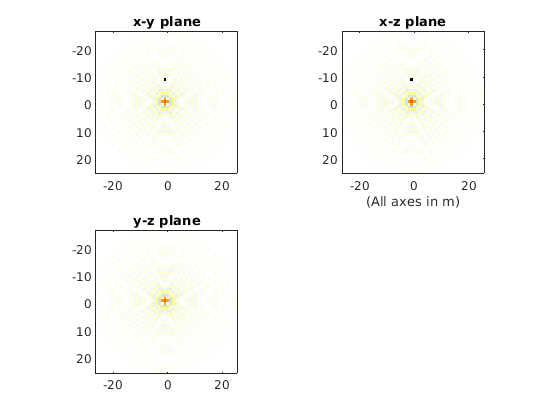

Error using waitbar (line 103)
The second argument must be a message character vector or a handle to an existing waitbar.

Error in kspaceFirstOrder3D (line 1162)
        waitbar(t_index / kgrid.Nt, pbar);

Error in 

[t_array,scale,prefix,in_p,kwave_out_p] = monopole_sound_source(p_source,p_receiver,frequency,dimension,spacing,Nt,dt,k_alpha);

### Image Source Method

order = 7;
[~, ism_out_p] = image_source_pressure_wave(p_source,p_receiver,dimension,t_array,spacing,c,frequency,Q,rho,order,alpha,0);

### Plotting

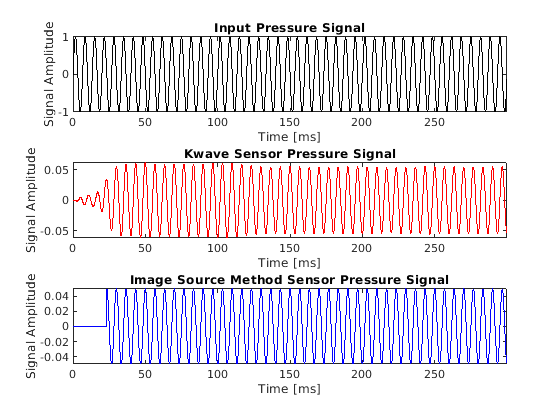

figure;
% -------- Input pressure ---------
subplot(3, 1, 1);
plot(t_array * scale, in_p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Input Pressure Signal');
% ------------ Kwave ---------------
subplot(3, 1, 2);
plot(t_array * scale, kwave_out_p, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Kwave Sensor Pressure Signal');
% ------ Image Source Method -------
subplot(3, 1, 3);
plot(t_array * scale, ism_out_p, 'b-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Image Source Method Sensor Pressure Signal');

### Difference between kwave and image source implementation

diff = abs(ism_out_p - kwave_out_p);
figure;
mean(diff)

ans = 0.0140

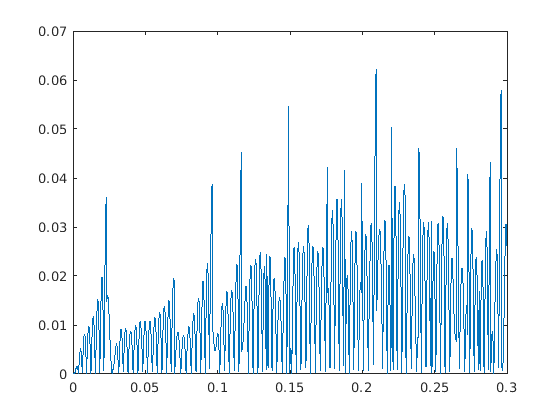

plot(t_array,diff);